# **Visualizing effect size for paired T sing along vs rest**

clear all
% Specify directories and patients
subjects_path='/Volumes/LASA/Aphasia_project/tb-fMRI/code/L2/paired T test/';
data_path='/Volumes/LASA/Aphasia_project/tb-fMRI/data/LASA/';
output_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/effect_size/flex/singavsrest/';
derdir='derivatives';
L1dir='SPM_first_level';
L1folder='L1_dur0_explbase_microres72_art_explmask_TU_missed';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/tbfMRI_LASA_current_code/notebooks/effect_size'; %add code path

We will extract the peak values from the coordinates with significant results in the paired T-test and flexible factorial for the corresponding contrasts:

- Flexible ABvsBA&TP2vsTP1, Tydyy-Uulaa Singing along vs rest: STG R (48,-12,15)

% Save peak value and contrast name to variable
peak3=[48,-12,15]; %flexible singavsrest MNI coord in mm

## Contrast 1: Flexible Tydyy-Uulaa Sing along vs Rest

cd(subjects_path)
load('subjects_s3')
subjects_s3(ismember({subjects_s3.name}, {'sub-14'})) = [];
subjects=subjects_s3;

%Select pair of scans for each group
ng1=1; ng2=1;
ses_pre='ses-001'; ses_post='ses-002';
for sbj = 1:size(subjects, 1)
    disp(subjects(sbj).name)
    if subjects(sbj).group==1
        sub_path_pre_g1= fullfile(data_path, subjects(sbj).name, ses_pre, derdir,L1dir, L1folder);
    cd(sub_path_pre_g1), load('SPM.mat')
        con_idx_pre_g1=find(ismember({SPM.xCon.name}, {'Sing_along>baseline'}));
        if ~isempty(con_idx_pre_g1)
            if con_idx_pre_g1 >9
                con_pre_g1{ng1,1}=spm_select('List', fullfile(sub_path_pre_g1),['^con_00' num2str(con_idx_pre_g1) '.*\.nii$']);
            elseif ~isempty(con_idx_pre_g1) && con_idx_pre_g1 <10
                con_pre_g1{ng1,1}=spm_select('List', fullfile(sub_path_pre_g1),['^con_000' num2str(con_idx_pre_g1) '.*\.nii$']);
            end
            con_fnames_pre_g1{ng1,1}=fullfile(sub_path_pre_g1, con_pre_g1{ng1,1});
        end
        clear SPM
        sub_path_post_g1= fullfile(data_path, subjects(sbj).name, ses_post, derdir,L1dir, L1folder);
    cd(sub_path_post_g1), load('SPM.mat')
        con_idx_post_g1=find(ismember({SPM.xCon.name}, {'Sing_along>baseline'}));
        if ~isempty(con_idx_post_g1)
            if con_idx_post_g1 >9
                con_post_g1{ng1,1}=spm_select('List', fullfile(sub_path_post_g1),['^con_00' num2str(con_idx_post_g1) '.*\.nii$']);
            elseif ~isempty(con_idx_post_g1) && con_idx_post_g1 <10
                con_post_g1{ng1,1}=spm_select('List', fullfile(sub_path_post_g1),['^con_000' num2str(con_idx_post_g1) '.*\.nii$']);
            end
            con_fnames_post_g1{ng1,1}=fullfile(sub_path_post_g1, con_post_g1{ng1,1});
        end
        clear SPM
        ng1=ng1+1;
    elseif subjects(sbj).group==2
sub_path_pre_g2= fullfile(data_path, subjects(sbj).name, ses_pre, derdir,L1dir, L1folder);
    cd(sub_path_pre_g2), load('SPM.mat')
        con_idx_pre_g2=find(ismember({SPM.xCon.name}, {'Sing_along>baseline'}));
        if ~isempty(con_idx_pre_g2)
            if con_idx_pre_g2 >9
                con_pre_g2{ng2,1}=spm_select('List', fullfile(sub_path_pre_g2),['^con_00' num2str(con_idx_pre_g2) '.*\.nii$']);
            elseif ~isempty(con_idx_pre_g2) && con_idx_pre_g2 <10
                con_pre_g2{ng2,1}=spm_select('List', fullfile(sub_path_pre_g2),['^con_000' num2str(con_idx_pre_g2) '.*\.nii$']);
            end
            con_fnames_pre_g2{ng2,1}=fullfile(sub_path_pre_g2, con_pre_g2{ng2,1});
        end
        clear SPM
        sub_path_post_g2= fullfile(data_path, subjects(sbj).name, ses_post, derdir,L1dir, L1folder);
    cd(sub_path_post_g2), load('SPM.mat')
        con_idx_post_g2=find(ismember({SPM.xCon.name}, {'Sing_along>baseline'}));
        if ~isempty(con_idx_post_g2)
            if con_idx_post_g2 >9
                con_post_g2{ng2,1}=spm_select('List', fullfile(sub_path_post_g2),['^con_00' num2str(con_idx_post_g2) '.*\.nii$']);
            elseif ~isempty(con_idx_post_g2) && con_idx_post_g2 <10
                con_post_g2{ng2,1}=spm_select('List', fullfile(sub_path_post_g2),['^con_000' num2str(con_idx_post_g2) '.*\.nii$']);
            end
            con_fnames_post_g2{ng2,1}=fullfile(sub_path_post_g2, con_post_g2{ng2,1});
        end
        clear SPM
        ng2=ng2+1;
    end
end

sub-01
sub-02
sub-05
sub-06
sub-07
sub-08
sub-09
sub-10
sub-11
sub-13
sub-16
sub-20
sub-21
sub-22
sub-23
sub-25
sub-26
sub-29
sub-30



% Get contrast estimate value at the peak for g1 & g2 patients pre
for i=1:size(con_fnames_pre_g1,1)    
    V=spm_vol(con_fnames_pre_g1{i}); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak3(1,1) & XYZmm(2,:)==peak3(1,2) & XYZmm(3,:)==peak3(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(con_fnames_pre_g1{i});
    pa_int_peak_pre_g1{i,1}=str2num(subjects(i).name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak_pre_g1{i,2}=int;% Save intensity value for the peak from all patients
end

for i=1:size(con_fnames_pre_g2,1)    
    V=spm_vol(con_fnames_pre_g2{i}); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak3(1,1) & XYZmm(2,:)==peak3(1,2) & XYZmm(3,:)==peak3(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(con_fnames_pre_g2{i});
    pa_int_peak_pre_g2{i,1}=str2num(subjects(i).name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak_pre_g2{i,2}=int;% Save intensity value for the peak from all patients
end

% Get contrast estimate value at the peak for g1 & g2 patients post
for j=1:size(con_fnames_post_g1,1)    
    V=spm_vol(con_fnames_post_g1{j}); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak3(1,1) & XYZmm(2,:)==peak3(1,2) & XYZmm(3,:)==peak3(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(con_fnames_post_g1{j});
    pa_int_peak_post_g1{j,1}=str2num(subjects(j).name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak_post_g1{j,2}=int;% Save intensity value for the peak from all patients
end

for j=1:size(con_fnames_post_g2,1)    
    V=spm_vol(con_fnames_post_g2{j}); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak3(1,1) & XYZmm(2,:)==peak3(1,2) & XYZmm(3,:)==peak3(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(con_fnames_post_g2{j});
    pa_int_peak_post_g2{j,1}=str2num(subjects(j).name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak_post_g2{j,2}=int;% Save intensity value for the peak from all patients
end

## Plot Contrast Estimate at the Peak Value Pre Post

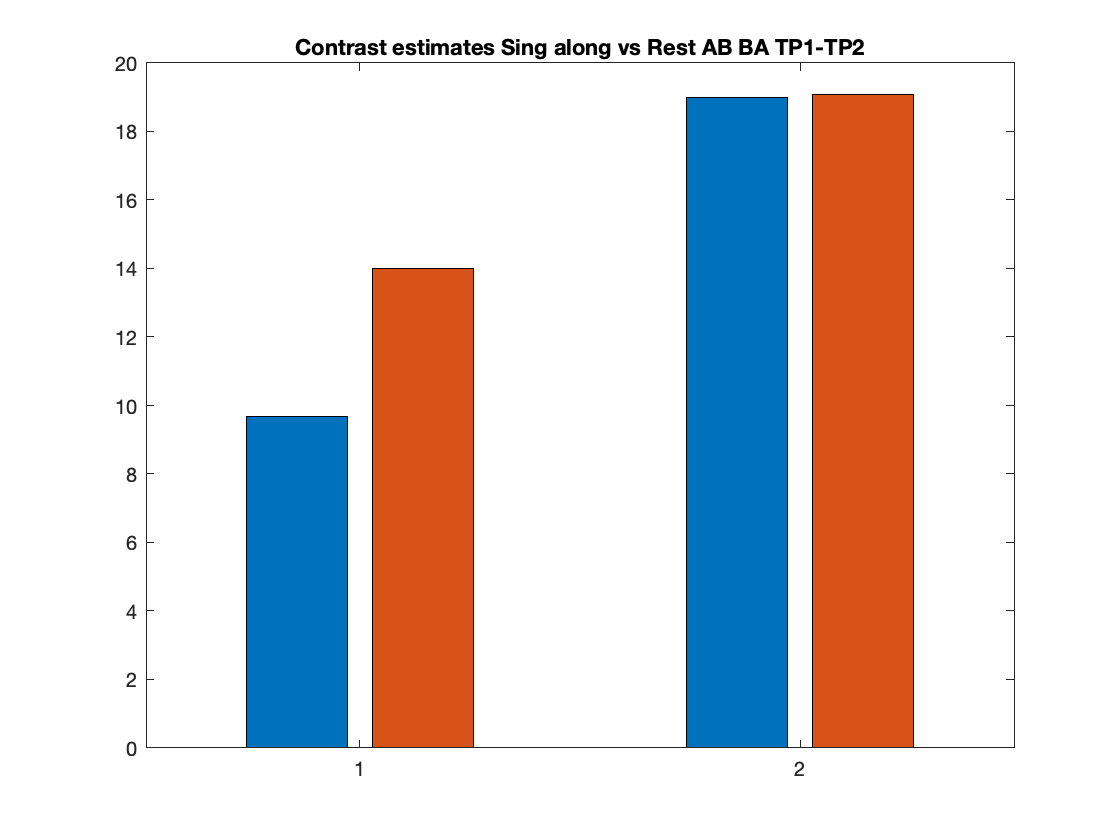

figure
x = [1 2];
pre_g1=mean(cell2mat(pa_int_peak_pre_g1(:,2)));pre_g2=mean(cell2mat(pa_int_peak_pre_g2(:,2)));
post_g1=mean(cell2mat(pa_int_peak_post_g1(:,2)));post_g2=mean(cell2mat(pa_int_peak_post_g2(:,2)));
vals = [[pre_g1 post_g1]; [pre_g2 post_g2]];
b = bar(x,vals);
title ('Contrast estimates Sing along vs Rest AB BA TP1-TP2')
cd(output_path)
saveas(gcf,['ContrastEstimates_Singavsrest_ABBA_TP1TP2.jpg'])

save('ContrastEstimates_singavsrest_ABBA_TP1TP2','pa_int_peak_pre_g1','pa_int_peak_pre_g2','pa_int_peak_post_g1','pa_int_peak_post_g2')